% gpuDeviceCount("available")
% gpuDeviceTable

out

out =   Simulink.SimulationOutput:

                   cost: [1x1 timeseries] 
             laneVector: [1x1 timeseries] 
                  lanes: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                     mv: [1x1 timeseries] 
             mv_command: [1x1 timeseries] 
                mv_real: [1x1 timeseries] 
                 mv_seq: [1x1 timeseries] 
             solverStat: [1x1 timeseries] 
                 status: [1x1 timeseries] 
                   tout: [1082x1 double] 
            vehiclePose: [1x1 struct] 
      vehiclePose_truth: [1x1 struct] 
              waypoints: [1x1 timeseries] 
     waypoints_relative: [1x1 timeseries] 
                  x_seq: [1x1 timeseries] 
                  y_seq: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


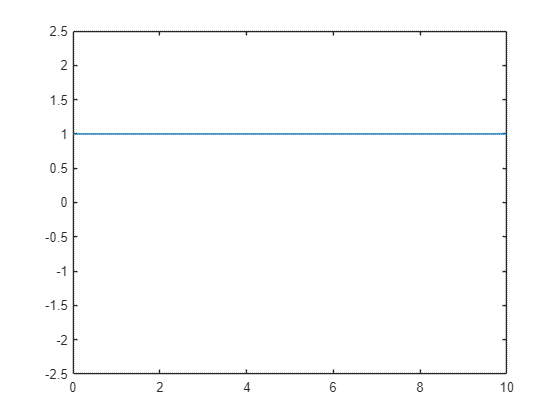

% out.waypoints_relative.Data
% out.waypoints.Data(1,:,:)
% out.vehiclePose_truth.Yaw.Data


figure
plot(out.solverStat.Time, out.solverStat.Data)
axis([T0 Te -2.5 2.5])

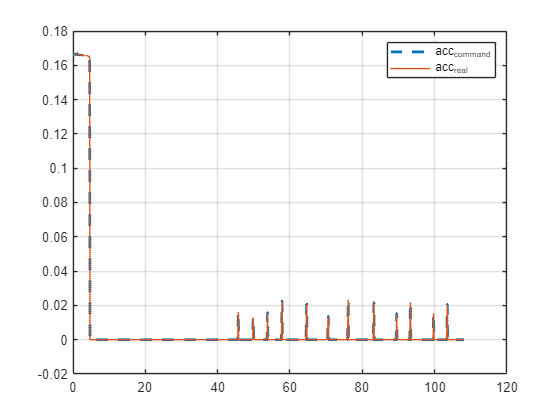


i=11;


mv_real=out.mv_real.Data;
t_mv_real=out.mv_real.Time;
mv_command=out.mv_command.Data;
t_mv_command=out.mv_command.Time;

figure
plot(t_mv_command,mv_command(:,1),'--',"LineWidth",2)
hold on
plot(t_mv_real,mv_real(:,1))
grid on
legend('acc_command','acc_real')

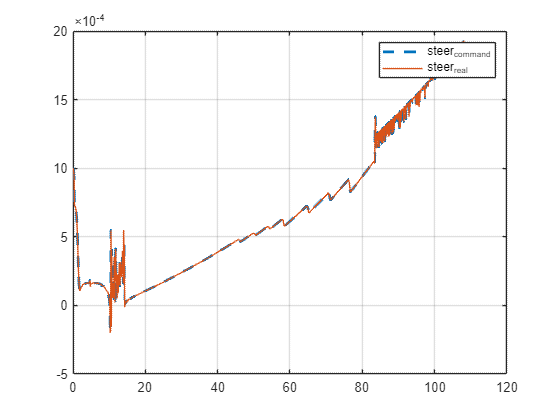


figure
plot(t_mv_command,mv_command(:,2),'--',"LineWidth",2)
hold on
plot(t_mv_real,mv_real(:,2))
grid on
legend('steer_command','steer_real')

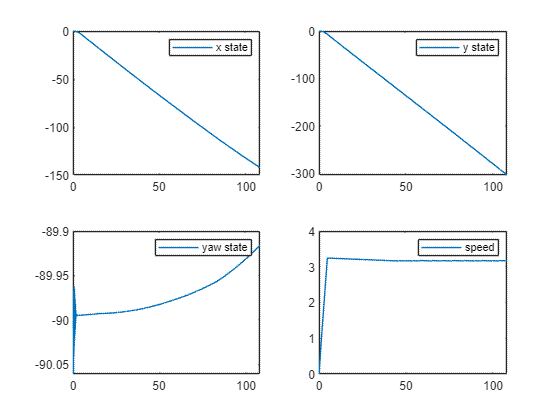

vx_state=out.vehiclePose.Velocity.Data(1,1,:);
vx_state=reshape(vx_state,[size(vx_state,3),1]);
vy_state=out.vehiclePose.Velocity.Data(1,2,:);
vy_state=reshape(vy_state,[size(vy_state,3),1]);
v_state=(vx_state.^2+vy_state.^2).^0.5;

x_state=out.vehiclePose.Position.Data(1,1,:);
x_state=reshape(x_state,[size(x_state,3),1]);
y_state=out.vehiclePose.Position.Data(1,2,:);
y_state=reshape(y_state,[size(y_state,3),1]);
yaw_state=out.vehiclePose.Yaw.Data(1,1,:);
yaw_state=reshape(yaw_state,[size(yaw_state,3),1]);

t_state=out.vehiclePose.ActorID.Time;

figure
subplot(2,2,1)
plot(t_state,x_state)
legend('x state')
subplot(2,2,2)
plot(t_state,y_state)
legend('y state')
subplot(2,2,3)
plot(t_state,yaw_state)
legend('yaw state')
subplot(2,2,4)
plot(t_state,v_state)
legend('speed')

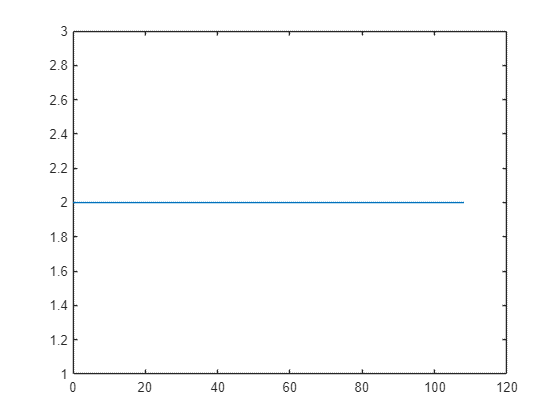


t_lanes=out.lanes.Time.Data;
t_lanes=reshape(t_lanes,1,length(t_lanes));

numLanes=out.lanes.NumLaneBoundaries.Data;
numLanes=reshape(numLanes,1,length(numLanes));
figure
plot(t_lanes,numLanes)

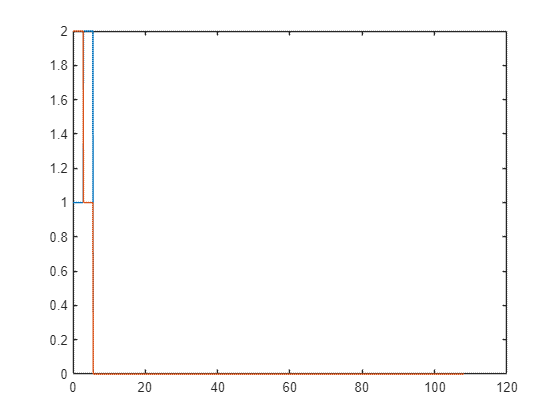


laneType_l=out.lanes.LaneBoundaries(1).BoundaryType.Data;
laneType_l=reshape(laneType_l,1,length(laneType_l));
laneType_r=out.lanes.LaneBoundaries(2).BoundaryType.Data;
laneType_r=reshape(laneType_r,1,length(laneType_r));
figure
plot(t_lanes,laneType_l)
hold on
plot(t_lanes,laneType_r)


lane=out.lanes.LaneBoundaries(1)

lane = struct with fields:
              Curvature: [1×1 timeseries]
    CurvatureDerivative: [1×1 timeseries]
            CurveLength: [1×1 timeseries]
           HeadingAngle: [1×1 timeseries]
          LateralOffset: [1×1 timeseries]
           BoundaryType: [1×1 timeseries]
               Strength: [1×1 timeseries]
                  Width: [1×1 timeseries]


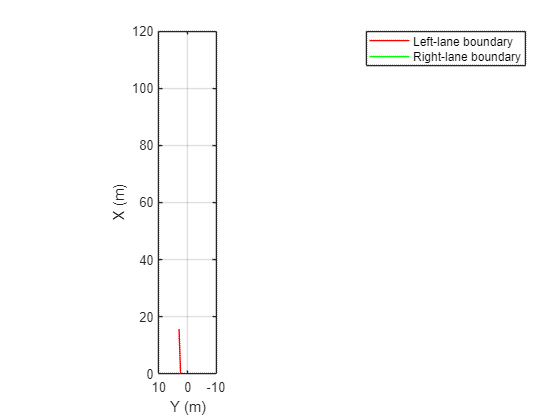


LB_l=clothoidLaneBoundary;
LB_l.Curvature=lane.Curvature.Data(:,:,i);
LB_l.CurvatureDerivative=lane.CurvatureDerivative.Data(:,:,i);
LB_l.CurveLength=lane.CurveLength.Data(:,:,i);
LB_l.HeadingAngle=lane.HeadingAngle.Data(:,:,i);
LB_l.LateralOffset=lane.LateralOffset.Data(:,:,i);
bep = birdsEyePlot('XLimits',[0 120],'YLimits',[-10 10]);
lbPlotter = laneBoundaryPlotter(bep,'DisplayName','Left-lane boundary','Color','r');
rbPlotter = laneBoundaryPlotter(bep,'DisplayName','Right-lane boundary','Color','g');
plotLaneBoundary(lbPlotter,LB_l)
grid
hold on

LB_vec=out.laneVector.Data(:,:,i)

LB_vec =     0.0106    0.0106
   -0.0000   -0.0000
   16.9883   16.9998
    1.8425    1.8414
    2.4223   -1.1775
    1.0000    2.0000


% x_sample=linspace(0,100,101);
% LB_l_y = coumputeBoundary(LB_l_vec(:,1), x_sample);
% plot(x_sample,LB_l_y,'b^')

state_pos=out.vehiclePose.Position.Data(:,1:2,i);
state_vel=out.vehiclePose.Velocity.Data(:,1:2,i);
state_yaw=out.vehiclePose.Yaw.Data(:,:,i);

waypoint_bf=out.waypoints_relative.Data(1,:,i)

waypoint_bf =   536.2639   47.9825



mv_seq=out.mv_seq.Data(:,:,i)

mv_seq =     0.1663    0.0006
    0.1479    0.0006
    0.1294    0.0006
    0.1109    0.0005
    0.0396    0.0004
    0.0396    0.0004
    0.0396    0.0004
    0.0396    0.0004
    0.0396    0.0004
    0.0396    0.0004


action_i=out.mv.Data(i,:)

action_i =     0.1663    0.0006


% action_i=mv_seq(1,:)

state_i=[0,0,0,state_vel(1)]'

state_i =          0
         0
         0
   -0.3351



nextState_dynamics = vehicleDynamics_Simple(state_i, action_i, ...
    Ts, L, waypoints, ...
    cosFuncWeights.weights, EgoCar1_params.Limits.limits, ...
    2, LB_vec)

nextState_dynamics =    -0.0335
         0
   -0.0000
   -0.3185


nextState_pose=out.vehiclePose.Position.Data(:,1:2,i+1);
deltaState_pos=world2body(state_pos', state_yaw, nextState_pose')';
deltaState_yaw=out.vehiclePose.Yaw.Data(:,:,i+1)-state_yaw;
newState_vel=out.vehiclePose.Velocity.Data(:,1,i+1);
nextState_simulation=[deltaState_pos deltaState_yaw newState_vel]'

nextState_simulation =     0.0642
   -0.0365
   -0.0452
   -0.3124


out.vehiclePose.Position.Data(:,1:2,i:i+10)-out.vehiclePose.Position.Data(:,1:2,i)

ans = ans(:,:,1) =

     0     0


ans(:,:,2) =

   -0.0365   -0.0642


ans(:,:,3) =

   -0.0684   -0.1388


ans(:,:,4) =

   -0.1117   -0.2157


ans(:,:,5) =

   -0.1495   -0.3032


ans(:,:,6) =

   -0.1993   -0.3926


ans(:,:,7) =

   -0.2434   -0.4924


ans(:,:,8) =

   -0.2983   -0.5944


ans(:,:,9) =

   -0.3502   -0.7053


ans(:,:,10) =

   -0.4088   -0.8204


ans(:,:,11) =

   -0.4685   -0.9423


x_i=out.x_seq.Data(:,:,i)

x_i =          0         0         0    0.4939
    0.0494         0    0.0000    0.5105
    0.1004    0.0000    0.0000    0.5253
    0.1530    0.0000    0.0000    0.5383
    0.2068    0.0000    0.0000    0.5493
    0.2617    0.0000    0.0000    0.5533
    0.3171    0.0000    0.0000    0.5573
    0.3728    0.0000    0.0000    0.5612
    0.4289    0.0000    0.0000    0.5652
    0.4854    0.0000    0.0000    0.5691


u_i=out.mv_seq.Data(:,:,i);
weight_LK=cosFuncWeights.weights(1:2,4)

Index in position 1 exceeds array bounds. Index must not exceed 1.

cost_test = laneKeepingTerm(x_i, 1, LB_vec, weight_LK)